%https://la.mathworks.com/help/robotics/ref/importrobot.html
robot = importrobot('urdf/manipulator.urdf');
robot.DataFormat = 'row';
jointData = table2array(datos);

%https://la.mathworks.com/help/robotics/ref/rigidbodytree.massmatrix_es.html#bvlvr8l-1-robot
M = massMatrix(robot);

%https://la.mathworks.com/help/robotics/ref/rigidbodytree.velocityproduct.html#refsect-extended-capabilities
% qd = [0 0 0.2 0.3 0 0];
% tau = -velocityProduct(robot,[],qd);

**Jacobiano (configuracion inicial)**

%https://la.mathworks.com/help/robotics/ref/rigidbodytree.geometricjacobian.html
% conf2 = [0.659 0.831 -1.114 -0.009 0.267 0.638];
% geoJacob = geometricJacobian(robot,conf2,'link_6');


**Valores Propios y Determinante del Jacobiano**

% vp = eig(geoJacob);
% detJacob = det(geoJacob);

**Dinámicas directas debidas a fuerzas externas en el modelo de árbol de cuerpo rígido**

% %https://la.mathworks.com/help/robotics/ref/rigidbodytree.forwarddynamics.html
% robot.Gravity = [0 0 -9.81];
% q = homeConfiguration(robot);
% qdd = forwardDynamics(robot,q,[],[],[]);
% gtau = gravityTorque(robot,q);

**Calcular dinámicas inversas para configurar una articulación estática**

% tau_home = inverseDynamics(robot,q);


js = 1;
for i=1:3:length(jointData)
    desp_states(js,:) = jointData(i,:);
    desp_goal(js, : ) = jointData(i+1,:);
    determinante(js)=det(geometricJacobian(robot,deg2rad(jointData(i,:)),'link_6'));
    gtau(js,:) = gravityTorque(robot,deg2rad(jointData(i,:)));
    js = js+1;
end

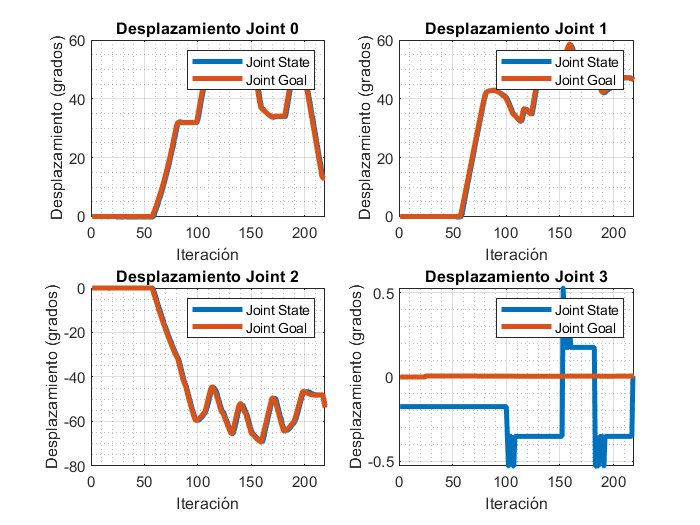

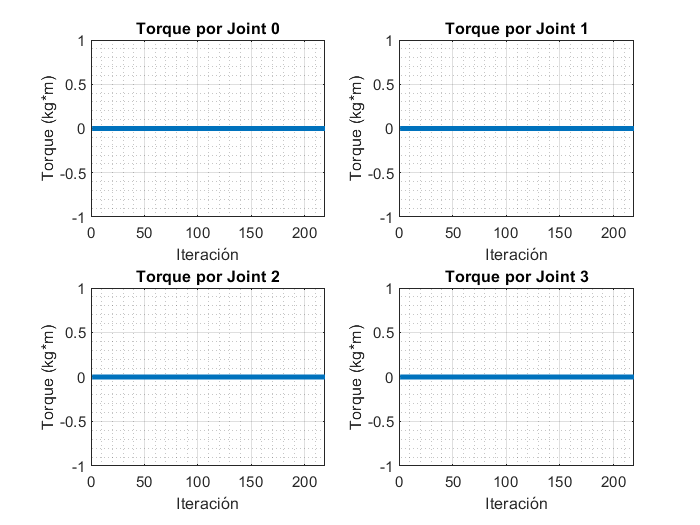

%%plot
for j = 1:4
    figure(1)
    subplot(2,2,j)
    plot(desp_states(:,j),"LineWidth",3)
    grid on
    grid minor
    title("Desplazamiento Joint " + (j - 1))
    xlabel("Iteración")
    ylabel("Desplazamiento (grados)")
    hold on
    plot(desp_goal(:,j),"LineWidth",3)
    legend('Joint State', 'Joint Goal')
    
    figure(2)
    subplot(2,2,j)
    plot(gtau(:,j),"LineWidth",3)
    grid on
    grid minor
    title("Torque por Joint " + (j - 1))
    xlabel("Iteración")
    ylabel("Torque (kg*m)")
    
end

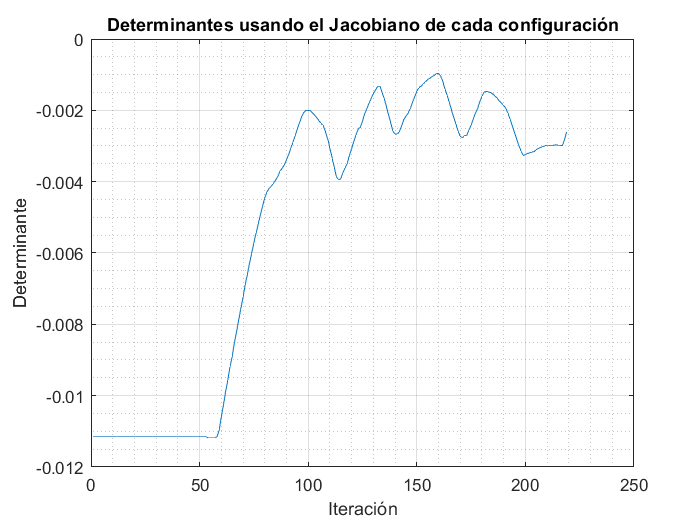

figure(3)
plot(determinante)
grid on
grid minor
title("Determinantes usando el Jacobiano de cada configuración")
xlabel("Iteración")
ylabel("Determinante")